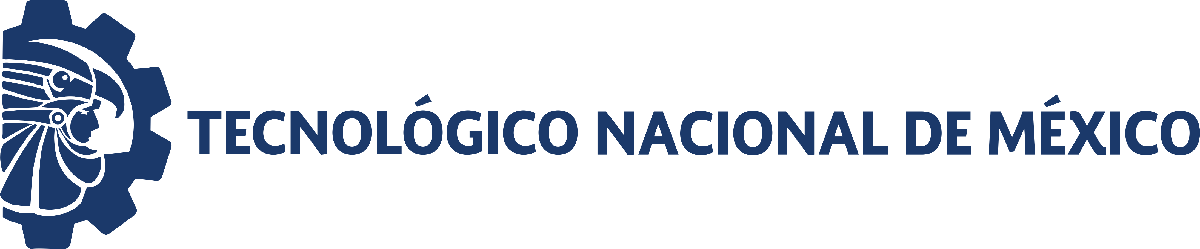                                 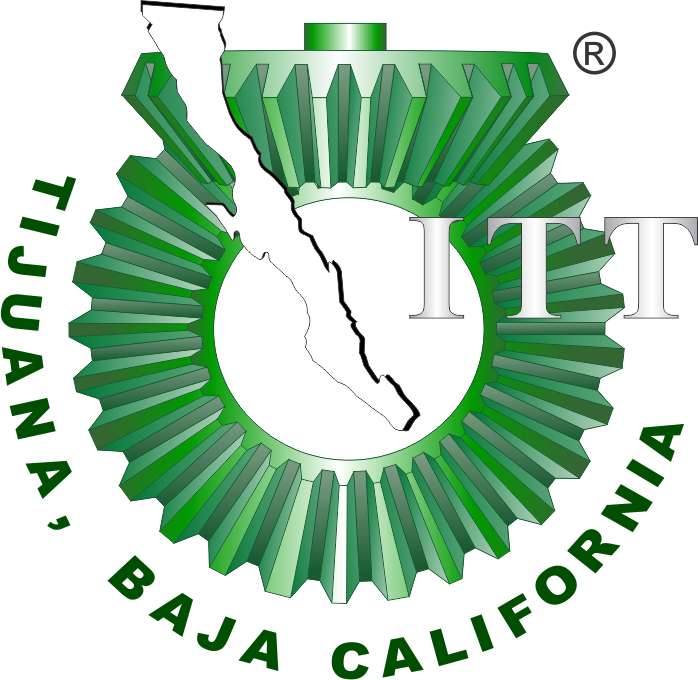

# Práctica cero: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

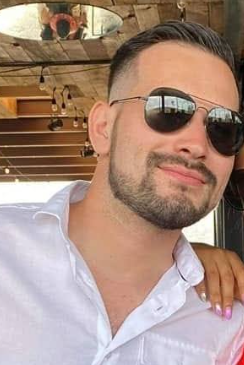

Nombre del alumno: Diego David Villaseñor Lopez

Número de control: 22210431

Correo institucional: l22210431**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
parameters.Solver='ode45';
parameters.MaxStep='1E-3';
parameters.StopTime='10';

## Sistema

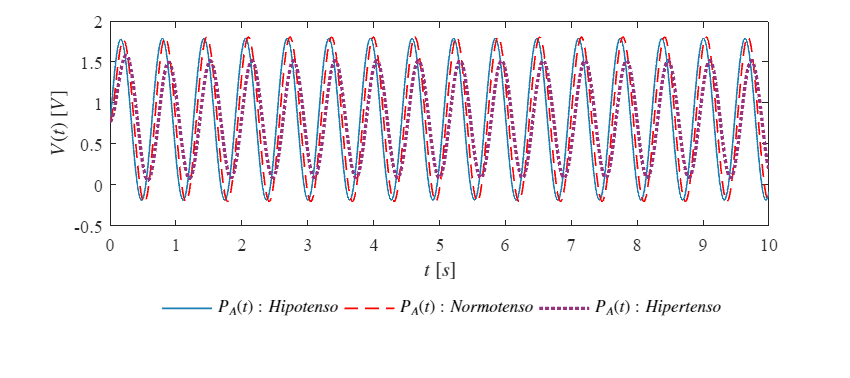

file='Sistema';
open_system(file);
x=sim(file,parameters);
opt=1;
s='Sistema';
plotsignals(x.t,x.Ppx,x.Ppy,x.Ppz,opt,s)

## Hipotenso

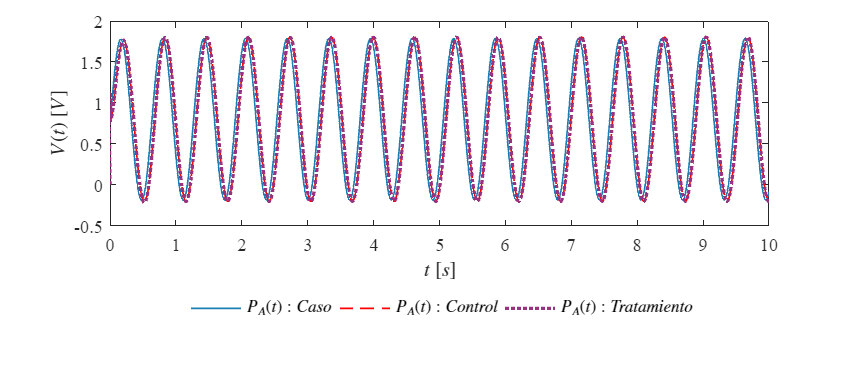

file='Hipotenso';
open_system(file);
x=sim(file,parameters);
opt=2;
s='Hipotenso';
plotsignals(x.t,x.Ppx,x.Ppy,x.Ppz,opt,s)

## Hipertenso

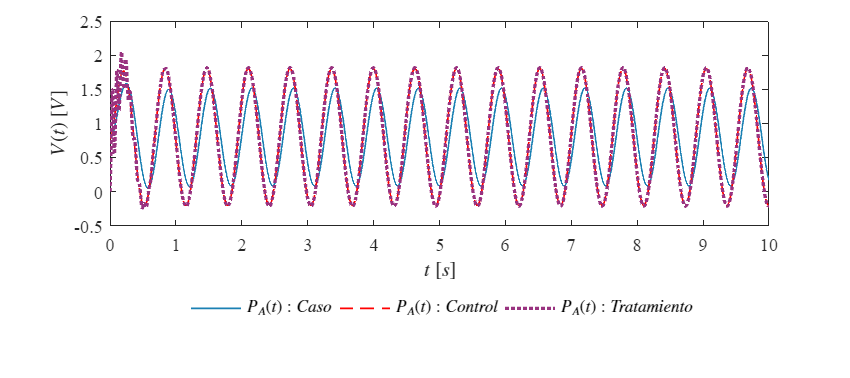

file='Hipertenso';
open_system(file);
x=sim(file,parameters);
opt=3;
s='Hipertenso';
plotsignals(x.t,x.Ppx,x.Ppy,x.Ppz,opt,s)

## Funcion: Respuesta a las señales 

function plotsignals(t,Ppx,Ppy,Ppz,opt,s)
    set(figure(),'Color','w')
    set(gcf,'units','Centimeters','Position',[1,1,18,8])
    set(gca,'FontName','Times New Roman')
    fontsize(11,'points')
    rojo=[1,0,0];
    morado=[.6,.2,.5];
    azul=[.1,.5,.7];
    hold on;grid off; box on;

    plot(t,Ppx,'LineWidth',1,'Color',azul)
    plot(t,Ppy,"--",'LineWidth',1,'Color',rojo)
    plot(t,Ppz,':','LineWidth',2,'Color',morado)

    xlabel('$t$ $[s]$','Interpreter','latex')
    ylabel('$V(t)$ $[V]$','Interpreter','latex')

    if s=="Sistema"
    L = legend('$P_{A}(t):Hipotenso$', '$P_A(t):Normotenso$', '$P_{A}(t):Hipertenso$');
set(L, 'Interpreter', 'latex', ...
       'Location', 'southoutside', ...
       'Orientation', 'horizontal', ...
       'Box', 'off');

    elseif s=="Hipertenso"
 L = legend('$P_{A}(t):Caso$', '$P_A(t):Control$', '$P_{A}(t):Tratamiento$');
set(L, 'Interpreter', 'latex', ...
       'Location', 'southoutside', ...
       'Orientation', 'horizontal', ...
       'Box', 'off');

    elseif s=="Hipotenso"
   L = legend('$P_{A}(t):Caso$', '$P_A(t):Control$', '$P_{A}(t):Tratamiento$');
set(L, 'Interpreter', 'latex', ...
       'Location', 'southoutside', ...
       'Orientation', 'horizontal', ...
       'Box', 'off');
    end

    exportgraphics(gcf,[s,'.pdf'],'ContentType','Vector')

end